# Control systems project - Linear inverted pendulum

## Dynamical system modelling

### Pendulum and cart

The nonlinear model describing the dynamical variations of the angular position of the pendulum $\theta$ and the linear position of the cart $x$ is described by the following nonlinear coupled second order differential equations

$(I + ml^2)\ddot{\theta} + f_p +mgl\sin\theta = -ml\ddot{x}\cos\theta  \\
(M+m)\ddot{x}+f_c+ml\ddot{\theta}\cos \theta-ml\dot{\theta}^2 \sin \theta = F \\$       (1)

where

- $M$is the mass of the cart

- $m$ is the mass of the pendulum

- $I$ is the inertia of the pendulum

- $f_c
$ is the cart friction

- $f_p$ is the pendulum friction

- $l$ is the half pendulum length

- $g$ is the gravitational constant

In order to decouple the equations it is helpful to define


$$a_0 = I + ml^2 \\
a_1 = f_p \\
a_2 = mgl\sin\theta \\
a_3 = ml\cos\theta \\
Y = \ddot\theta
\\
b_0 = M + m \\
b_1 = f_c \\
b_2 = ml\cos\theta = a_3 \\
b_3 = ml\dot\theta^2\sin\theta \\
X = \ddot x$$


As (1) then becomes


$$a_0Y + a_1 + a_2 = -a_3X \\
b_0X + b_1 + a_3Y - b_3 = F$$


From the first equation we find Y:


$$a_0Y + a_1 + a_2 = -a_3X \Leftrightarrow Y = \frac{1}{a_0}(-a_3X - a_1 - a_2)$$


Which is inserted in the second equation to get X:


$$b_0X + b_1 + a_3(\frac{1}{a_0}(-a_3X - a_1 - a_2)) - b_3 = F \Leftrightarrow \\
X(b_0 - \frac{a_3^2}{a_0}) + b1 - \frac{a_3(a_1 + a_2)}{a_0} - b_3 = F \Leftrightarrow \\
X = \frac{1}{b_0 - \frac{a_3^2}{a_0}}(F - b_1 + \frac{a_3(a_1 + a_2)}{a_0} + b_3)$$


Expression for X can the be inserted in to the first equation to get Y.


$$a_0Y + a_1 + a_2 = -a_3(\frac{1}{b_0 - \frac{a_3^2}{a_0}}(F - b_1 + \frac{a_3(a_1 + a_2)}{a_0} + b_3))  \Leftrightarrow \\
Y = \frac{1}{a_0}(-a_1 - a_2 -a_3(\frac{1}{b_0 - \frac{a_3^2}{a_0}}(F - b_1 + \frac{a_3(a_1 + a_2)}{a_0} + b_3))  )$$


### Motor dynamics

The linearized model describing the mechanical and electrical dynamics of a brushed DC motor is given by the equations

$J\ddot\theta + B\dot\theta = k_ti \\
L\dot i + Ri = V - k_e\dot\theta$     (2)

where

- $J
$is the rotor inertia

- $B$ is the viscous motor friction coefficient

- $k_t$ is the torque constant

- $k_e$ is the electromotive constant

- $L$ is the pendulum friction

- $R$ is the half pendulum length 

- $\theta$ is the rotor angle

- $i$ is the winding current

Laplace transforming (2) yields:


$$s^2J\theta + sB\theta = k_t i \\
sLi + Ri = V - sk_e\theta$$
 

It is customary to set $L = 0, k_t = k_e = K$. Inserting this into the system yields:

  
$$s^2J\theta + sB\theta = K i \\
Ri = V - sK\theta$$
 

Finding i from the second equation and substituting into the first one gives:

  
$$Ri = V - sK\theta \Leftrightarrow i = \frac{V - sK\theta}{R} \\

s^2J\theta + sB\theta = K \frac{V - sK\theta}{R} \\$$
 

Then from here we can find the transfer function $G(s) = \frac{\theta}{V}$:


$$s^2J\theta + sB\theta = K \frac{V - sK\theta}{R} \Leftrightarrow \\

s^2J\theta + s\theta(B + \frac{K}{R})= K \frac{V}{R} \Leftrightarrow \\

\theta(s^2J + sB + s(B + \frac{K}{R}))= K \frac{V}{R} \Leftrightarrow \\

\theta= K \frac{V}{R}\frac{1}{s^2J + s(B + \frac{K}{R})} \Leftrightarrow \\

\theta= V\frac{K}{s^2JR + s(BR + K)} \Leftrightarrow \\

\frac{\theta}{V} = \frac{K}{s^2JR + s(BR + K)} $$


The inverse laplace transform will then yield:


$$\ddot\theta JR + \dot\theta(BR + K) = KV$$


For a frictionless load, the J in this equation is the sum of the rotor inertia and load inertia. Rewriting the equation in simpler terms:


$$c_0 = JR \\
c_1 = BR + K \\
c_2 = K$$


$\ddot\theta c_0 + \dot\theta c_1 = Vc_2$(3)

### Joining the systems

The torque delivered by the DC motor is given by


$$\tau = k_ti - B\dot\phi$$


Substituting $i = \frac{V}{R} - \frac{k_e}{R}\dot\phi$ into the above equation gives:


$$\tau = \frac{k_tV}{R} - \frac{k_ek_t}{R}\dot\phi - B\dot\phi$$


The available torque for just the cart and pendulum will be the above torque, minus the torque produced by the rest of the drive train:


$$\tau_d = \frac{k_tV}{R} - \frac{k_ek_t}{R}\dot\phi - B\dot\phi - J_d\ddot\phi$$


where $J_d$ is the total inertia of the drive train (pulley's, belt's and rod's). The available drive force can be found by dividing the drive torque by the radius

$F= \frac{k_tV}{Rr} - \frac{k_ek_t}{Rr}\dot\phi - \frac{B}{r}\dot\phi - \frac{J_d}{r}\ddot\phi$  (3)

We can further connect the angular position of the motor and drive train with the linear displacement of the cart by $x = r\phi$. Thus changing coordinates in (1) from $x$ to $\phi$ yields

$(I + ml^2)\ddot{\theta} + f_p +mgl\sin\theta = -ml\ddot{\phi}r\cos\theta  \\
(M+m)\ddot{\phi}r+f_c+ml\ddot{\theta}\cos \theta-ml\dot{\theta}^2 \sin \theta = F $       (2)

Inserting equation (3) into (2) gives the final system which includes both motor dynamics as well as pendulum and cart dynamics

$(I + ml^2)\ddot{\theta} = -ml\ddot{\phi}r\cos\theta - f_p -mgl\sin\theta  \\


((M+m)r +\frac{J_d}{r})\ddot\phi = \frac{k_tV}{Rr} - \frac{k_ek_t}{Rr}\dot\phi - \frac{B}{r}\dot\phi - f_c + ml\dot{\theta}^2 \sin \theta - ml\ddot{\theta}\cos \theta$      (4)

In order to work with the equations they must be decoupled in terms of the second derivative of the two states. Firstly defining


$$a_0 = I + ml^2 \\
a_1 = mlr\cos\theta \\
a_2 = mgl\sin\theta \\
a_3 = f_p
\\
b_0 = ((M+m)r +\frac{J_d}{r}) \\
b_1 = ml\cos \theta \\
b_2 =  \frac{k_tV}{Rr} - \frac{k_ek_t}{Rr}\dot\phi - \frac{B}{r}\dot\phi + ml\dot{\theta}^2 \sin \theta \\
b_3 = f_c
$$


Simplifies (4) to

$a_0 \ddot{\theta} = -a_1\ddot{\phi} - a2 - a_3\\
b_0 \ddot{\phi} = -b_1\ddot{\theta} + b_2 - b_3$ (5)


$$X=\frac{1}{a_0 }\left(-a_1 Y-a_2 -a_3 \right)$$



$$Y=\frac{1}{b_0 }\left(-\frac{b_1 }{a_0 }\left(-a_1 Y-a_2 -a_3 \right)+b_2 -b_3 \right)$$



$$Y-\frac{b_1 }{b_0 a_0 }Y=\frac{1}{b_0 }\left(-\frac{b_1 }{a_0 }\left(-a_2 -a_3 \right)+b_2 -b_3 \right)$$



$$Y=\frac{1}{1-\frac{b_1 }{b_0 a_0 }}\frac{1}{b_0 }\left(-\frac{b_1 }{a_0 }\left(-a_2 -a_3 \right)+b_2 -b_3 \right)$$



$$Y=\frac{1}{b_0 -\frac{b_1 }{a_0 }}\left(-\frac{b_1 }{a_0 }\left(-a_2 -a_3 \right)+b_2 -b_3 \right)$$



$$X=\frac{1}{a_0 }\left(-a_1 \frac{1}{b_0 -\frac{b_1 }{a_0 }}\left(-\frac{b_1 }{a_0 }\left(-a_2 -a_3 \right)+b_2 -b_3 \right)-a_2 -a_3 \right)$$


Now solving (5) for the two second derivatives yields


$$\ddot{\theta} = -\frac{a_2b_0 + a_1b_2}{a_0b_0-a_1b_1} \\
\ddot{\phi} = \frac{a_0b_2 + a_2b_1}{a_0b_0-a_1b_1} \\$$


## Simulation

### Parameters

% DRIVE TRAIN ---------------------------------------------------------------

% 1) Large pulleys
r = 25e-3/2; % large pulley drive radius
mlt = 14.3e-3; % total mass of pulley
r1 = r;
r2 = 18e-3/2;
l1 = 9e-3;
l2 = 6e-3;
v1 = pi * r1^2 * l1 - pi * r^2 * l1;
v2 = pi * r2^2 * l2 - pi * r^2 * l2;
vlt = v1 + v2;
Jlp = 1/2*mlt*v1/vlt*(r1^2 + r^2) + 1/2*mlt*v2/vlt*(r2^2 + r^2); % moi of large pulley

% 2) Small pulley
rs = 12e-3/2; % small pulley drive radius
mst = 4.6e-3; % total mass of small pulley
r1 = r;
r2 = 16e-3/2;
l1 = 7.4e-3;
l2 = 7.6e-3;
v1 = pi * r1^2 * l1 - pi * rs^2 * l1;
v2 = pi * r2^2 * l2 - pi * rs^2 * l2;
vst = v1 + v2;
Jsp = 1/2*mst*v1/vst*(r1^2 + rs^2) + 1/2*mst*v2/vst*(r2^2 + rs^2); % moi of small pulley


% 3) Large belt
philb = 0.2e-3/23.3e-3; % belt mass pr. meter length
llb = 2*34.5e-2 + 2 * 28.5e-2 + 2 * 2*r*pi; % belt length
mlb = philb * llb; % belt mass
Jlb = mlb * r^2; % moi of large belt

% 4) Small belt
msb = 2e-3; 
Jsb = msb * rs^2;

% 5) Coupling rods
mr = 40.8e-3; % mass of rod
rr = 4e-3; % radius of rod
Jr = 1/2 * mr * rr^2; % moi of rod

% 6) Total drive
Jd = 2 * Jlp + 2 * Jsp + Jlb + Jsb; % total moi for drive train components

% MOTOR --------------------------------------------------------------------
R = 3.3; % armature resistance [Ω]
L = 1.25e-3; % armature inductance [H]
kt = 0.0285; % torque constant [Nm/A]
ke = 0.0285;% electromotive force constant [Vs/rad]
J = 1.12e-6; % rotor inertia [kg m^2]
B = 6.5559e-5; % viscous motor friction [Ns\m]

% PENDULUM AND CART
M =632; % mass of cart [kg]
m = 0.181; % mass of pendulum [kg]
I = 1/12*m*(2*L)^2; % moi of pendulum [kg m^2]
g = 9.8; % gravity constant [m/s^2]
l = 0.365/2; % lenght of pendulum rod [m]
c = 0.01; % friction coefficient pendulum [kg m^2/s]                ESTIMATE
b = 0.01;
mu_k = 0; % kinetic friction coefficient cart                     ESTIMATE
mu_s = 0; % static friction coefficient cart                      ESTIMATE
FN = (m + M)*g; % normal force on cart [N]
mu_v = 100; % viscous friction coefficient cart                     ESTIMATE
a_st = 0.1;   % can't remember the name                               ESTIMATE

% Simulation specific parameters
dtheta0 = 0; % pendulum angular velocity [rad/s]
theta0 = pi - 0.1; % pendulum angular position [rad]
dx0 = 0; % trolley linear velocity [m/s]
x0 = 0; % trolley linear position [m]
u0 = 0; % linear force applied to the trolley [N]
SIM_TIME = 80; % simulation time (can be changed as needed - if simulated for longer time, the pendulum returns to the downward position)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)\
SIMULINK_FILENAME = 'final\pend_m_motor.slx';

### Simulate and plot the model response

Firstly load in the experimental data

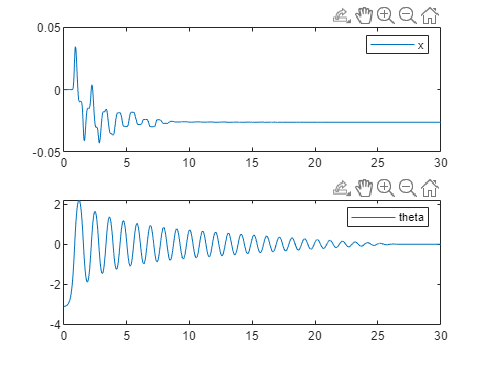

load zero_input.mat
x_meas = x;
theta_meas = deg2rad(theta);
%x_meas = x_meas(fix(1.5/0.001):end);
%theta_meas = theta_meas(fix(1.5/0.001):end);
%t = t(1:length(theta_meas));
x_exp = [t', x_meas'];
theta_exp = [t', theta_meas'];
figure;
subplot(2,1,1);
plot(t, x_meas);
legend('x');
subplot(2,1,2);
plot(t, theta_meas);
legend('theta');

theta0 = theta_meas(1); % update initial theta condition

Then simulate the model

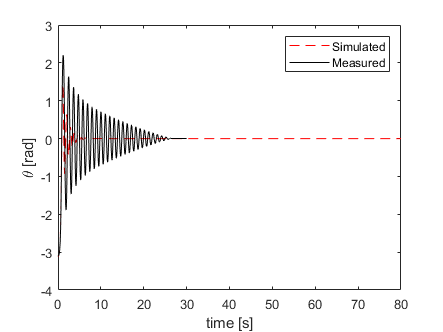

time = (0:STEP_SIZE:SIM_TIME)';
u = u0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time u]);

dtheta = rad2deg(logsout.getElement('dtheta').Values.Data);
theta = deg2rad(wrapTo180(rad2deg(logsout.getElement('theta').Values.Data)));
dx = logsout.getElement('dx').Values.Data;
x = logsout.getElement('x').Values.Data;

% Plot theta
figure;
plot(time, theta, '--r', t, theta_meas, 'k')
legend('Simulated', 'Measured')
ylabel('\theta [rad]');
xlabel('time [s]');

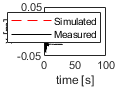


% plot x
figure;
plot(time, x, '--r', t, x_meas, 'k')
ylabel('x [m]')
xlabel('time [s]')
legend('Simulated', 'Measured')